## Loading the data

Breaking the training set into training and validation sets with a rough distribiution on 70% to 30%

% spectral_data = readtable('training.csv');
% test_data = readtable('testing.csv');
% 
% x_sp = table2array(spectral_data(2:198,2:28));
% y_sp = table2array(spectral_data(2:198,1));
% 
% x_test_sp = table2array(test_data(2:end,2:end));
% y_test_sp = table2array(test_data(2:end,1));
% 
% x_train_sp = x_sp(1:150, :);
% x_val_sp = x_sp(151:end, :);
% 
% y_train_sp = y_sp(1:140);
% y_val_sp = y_sp(141:end);

## Loading the data 

Breaking the testing set into testing and validation sets with a rough distribiution of 50% to 50%

spectral_data = readtable('training.csv');
test_data = readtable('testing.csv');

x_old_test = table2array(test_data(2:end,2:end));
y_old_test = table2array(test_data(2:end,1));

x_train_sp = table2array(spectral_data(2:end,2:end));
y_train_sp = table2array(spectral_data(2:end,1));

x_test_sp = x_old_test(1:162, :);
x_val_sp = x_old_test(162:end, :);

y_test_sp = y_old_test(1:162);
y_val_sp = y_old_test(162:end);

## Part 1: CKNN

We'll start with a simple CKNN model.

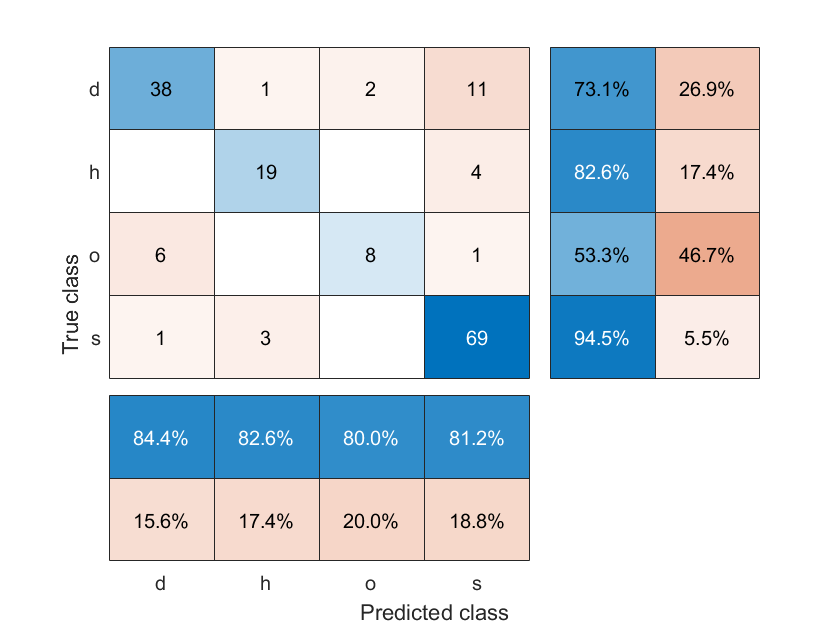

cknn_sp = fitcknn(x_train_sp, y_train_sp, 'NumNeighbors', 30);
pred = cknn_sp.predict(x_val_sp);
figure
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

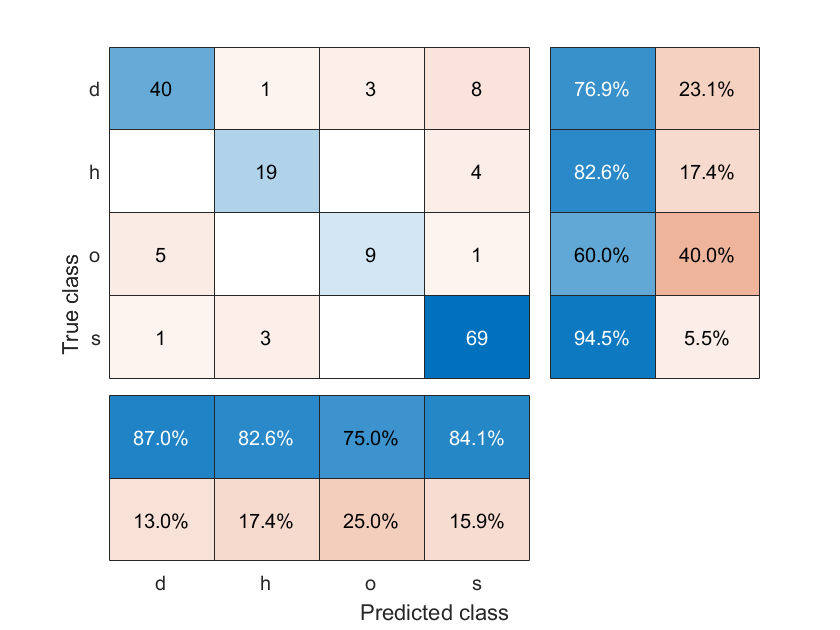

cknn_sp = fitcknn(x_train_sp, y_train_sp, 'NumNeighbors', 20);
pred = cknn_sp.predict(x_val_sp);
figure
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

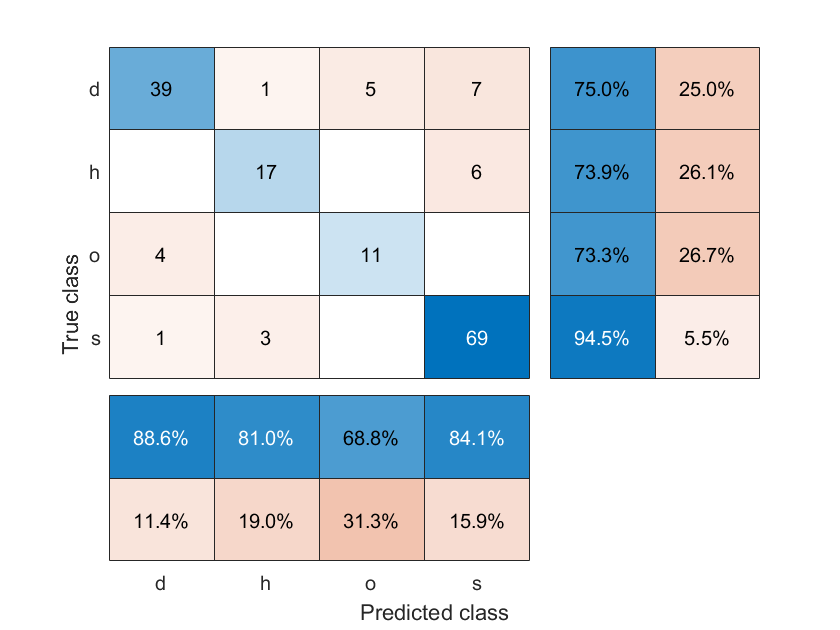

cknn_sp = fitcknn(x_train_sp, y_train_sp, 'NumNeighbors', 5);
pred = cknn_sp.predict(x_val_sp);
figure
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

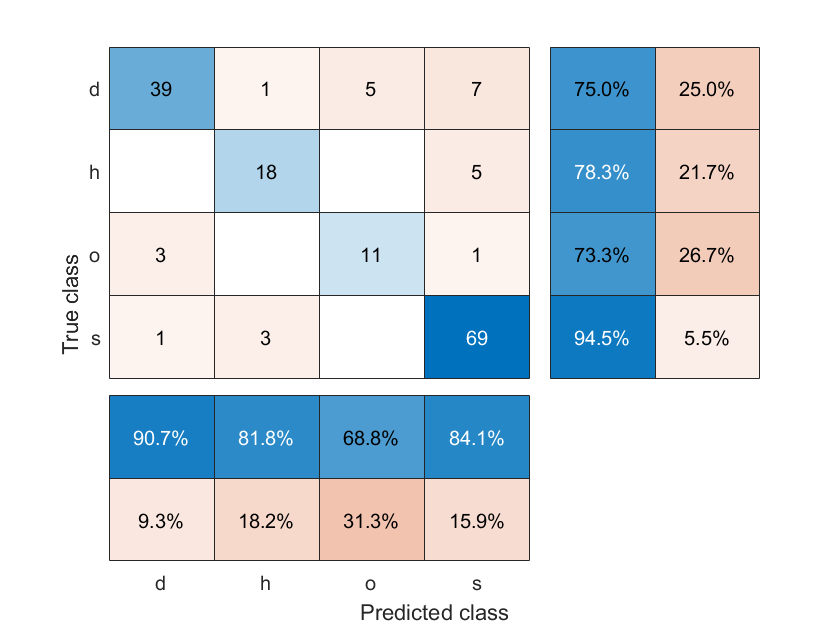

cknn_sp = fitcknn(x_train_sp, y_train_sp, 'NumNeighbors', 10);
pred = cknn_sp.predict(x_val_sp);
figure
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

NumNeighbors 10 is the most balanced model

Checking the distribution of the data

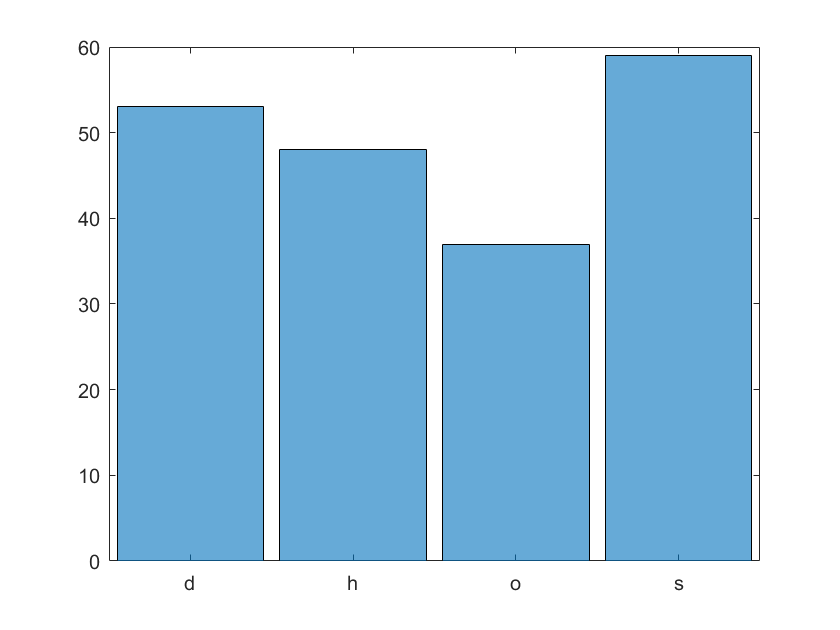

figure
cat_y_sp = categorical(y_train_sp);
histogram(cat_y_sp)

## Part 2: Ensember Classifier

#### Finding the best binary classifier:

**SVM-BoxConstraint:**

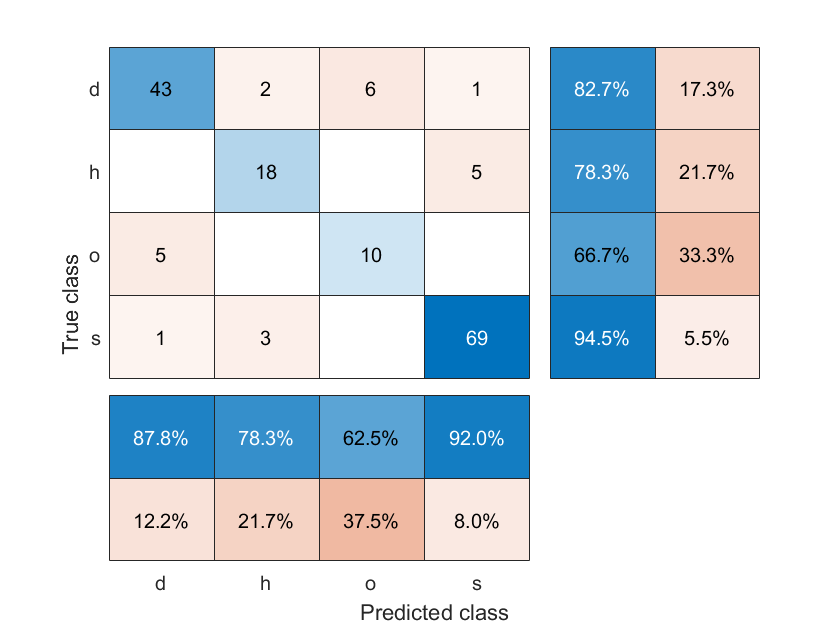

svm_inf = fitcecoc(x_train_sp, y_train_sp,'Learners',templateSVM('BoxConstraint', inf));
pred = svm_inf.predict(x_val_sp);
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

svm_1000 = fitcecoc(x_train_sp, y_train_sp,'Learners',templateSVM('BoxConstraint', 1000));
pred = svm_1000.predict(x_val_sp);
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

svm_1 = fitcecoc(x_train_sp, y_train_sp,'Learners',templateSVM('BoxConstraint', 1));
pred = svm_1.predict(x_val_sp);
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

svm_01 = fitcecoc(x_train_sp, y_train_sp,'Learners',templateSVM('BoxConstraint', 0.1));
pred = svm_01.predict(x_val_sp);
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

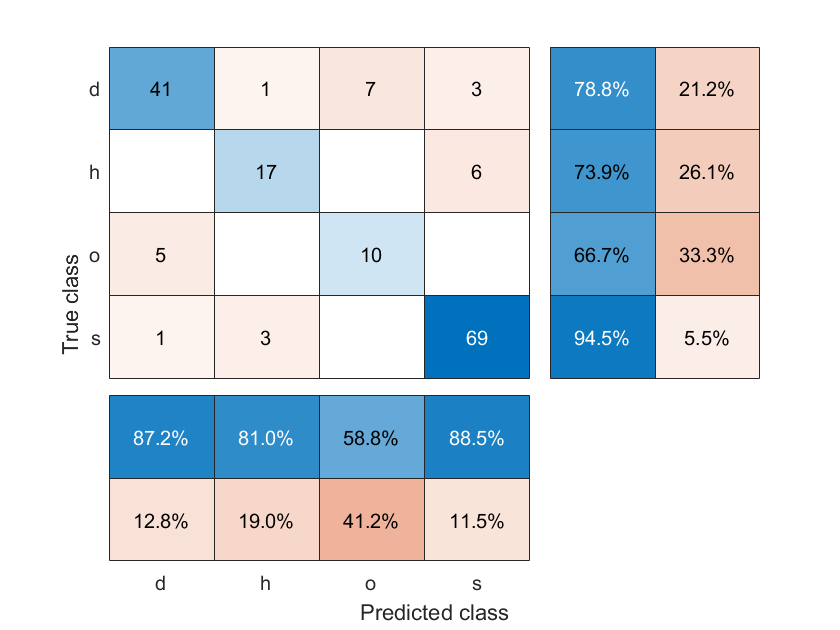

svm_001 = fitcecoc(x_train_sp, y_train_sp,'Learners',templateSVM('BoxConstraint', 0.001));
pred = svm_001.predict(x_val_sp);
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

Box Constraint does not seem to change the results above 0.001 which which causes a worse prediction and therefore the default box constraint (1) will be used.

**Standardize**

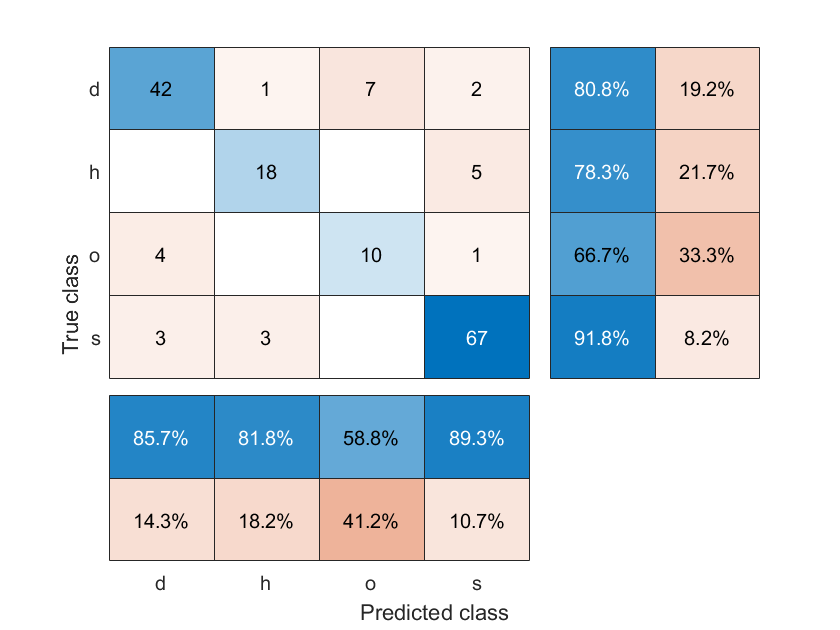


svm_1_s = fitcecoc(x_train_sp, y_train_sp,'Learners',templateSVM('BoxConstraint', 1, 'Standardize',true));
pred = svm_1_s.predict(x_val_sp);
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

Standardizing does not improve prediction

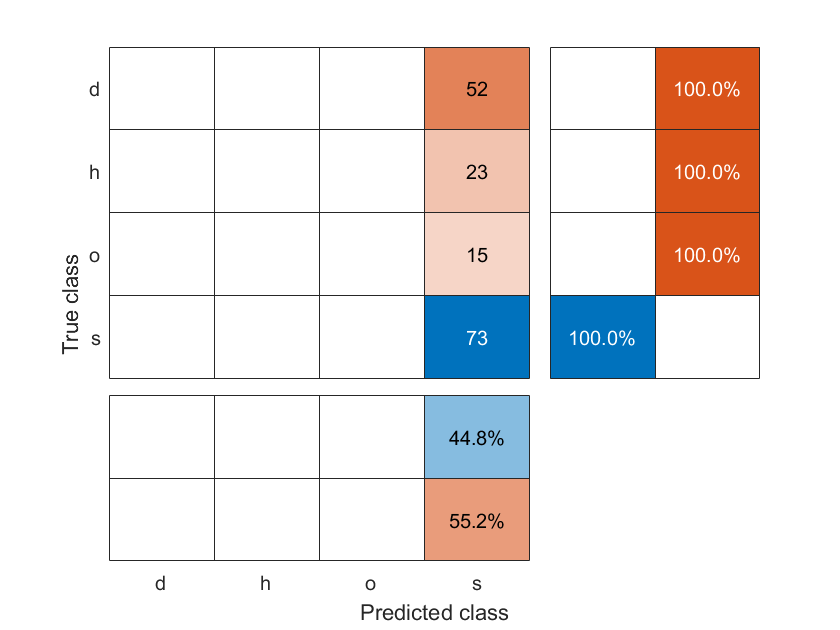

svm_1_rbf = fitcecoc(x_train_sp, y_train_sp,'Learners',templateSVM('KernelFunction','rbf'));
pred = svm_1_rbf.predict(x_val_sp);
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

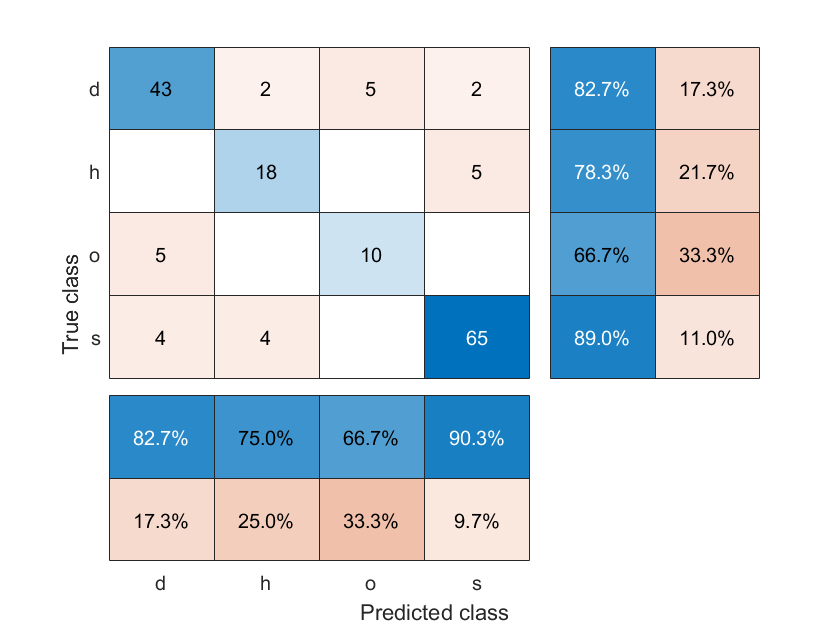

svm_1_rbf_100 = fitcecoc(x_train_sp, y_train_sp,'Learners',templateSVM('KernelFunction','rbf', 'KernelScale',100, 'BoxConstraint',1000, 'Standardize',true));
pred = svm_1_rbf_100.predict(x_val_sp);
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

The default svm still produces better results

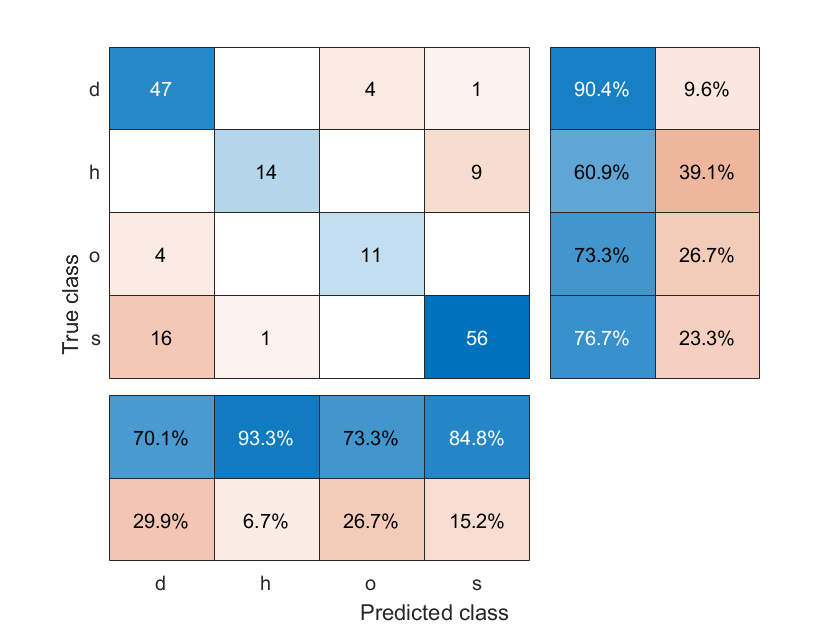

svm_1_poly_2 = fitcecoc(x_train_sp, y_train_sp,'Learners',templateSVM('KernelFunction','polynomial', 'Standardize',true, 'PolynomialOrder', 2));
pred = svm_1_poly_2.predict(x_val_sp);
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

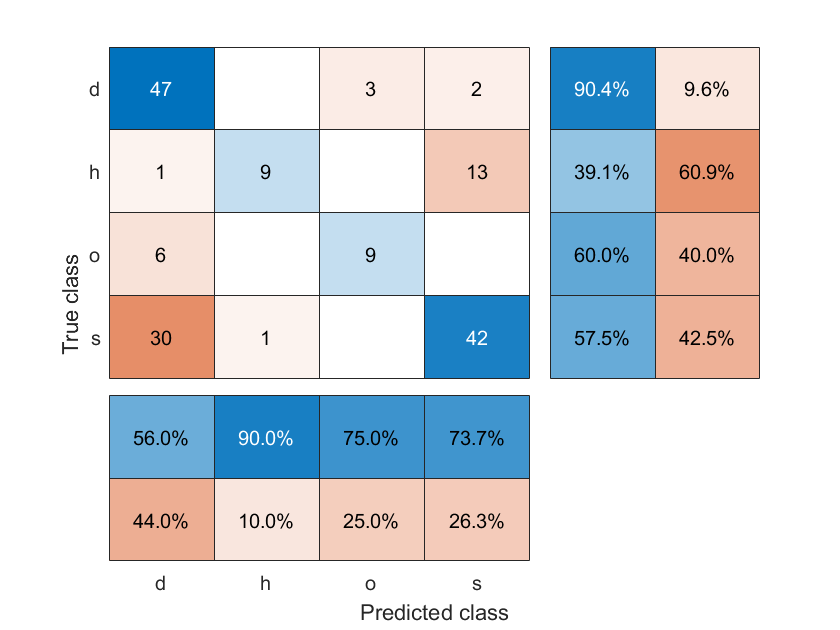

svm_1_poly_5 = fitcecoc(x_train_sp, y_train_sp,'Learners',templateSVM('KernelFunction','polynomial', 'Standardize',true, 'PolynomialOrder', 5));
pred = svm_1_poly_5.predict(x_val_sp);
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

Default svm model is still perfoming better

**Linear model**

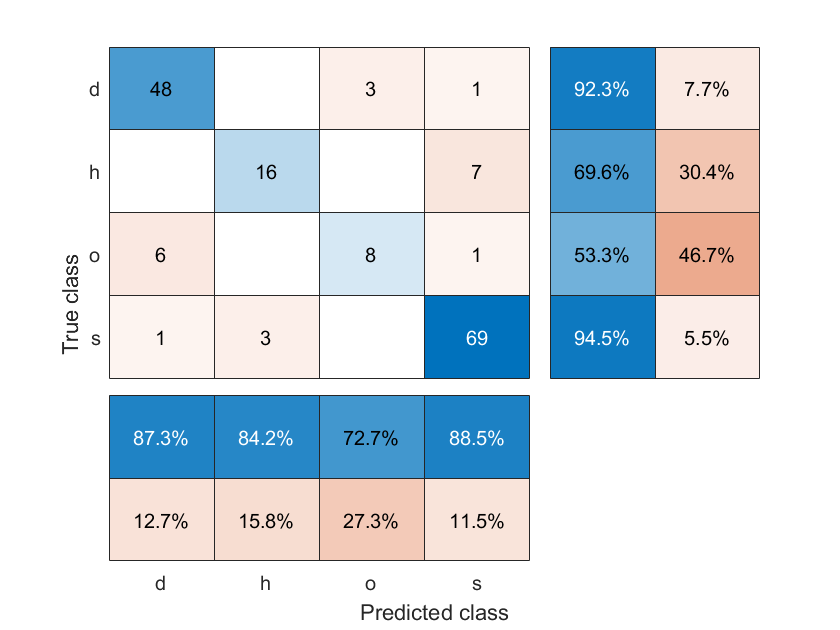

linear = fitcecoc(x_train_sp, y_train_sp,'Learners',templateLinear());
pred = linear.predict(x_val_sp);
confusionchart(y_val_sp, pred, 'ColumnSummary','column-normalized','RowSummary','row-normalized');

Best model was the default SVM

One vs One


svm_onevone = fitcecoc(x_train_sp, y_train_sp, 'Coding','onevsone');
disp(svm_onevone.CodingMatrix)

     1     1     1     0     0     0
    -1     0     0     1     1     0
     0    -1     0    -1     0     1
     0     0    -1     0    -1    -1



One vs All

svm_onevall = fitcecoc(x_train_sp, y_train_sp, 'Coding','onevsall');
disp(svm_onevall.CodingMatrix)

     1    -1    -1    -1
    -1     1    -1    -1
    -1    -1     1    -1
    -1    -1    -1     1



figure
subplot(1,2,1)
cat_y_val_sp = categorical(y_val_sp);
pred_onevone = svm_onevone.predict(x_val_sp);
disp("Accuracy (One v One): " + string(sum(pred_onevone == cat_y_val_sp) / length(cat_y_val_sp)))

Accuracy (One v One): 0.8589


confusionchart(y_val_sp, pred_onevone, 'ColumnSummary','column-normalized','RowSummary','row-normalized');
title('One vs One')
subplot(1,2,2)
pred_onevall = svm_onevall.predict(x_val_sp);
disp("Accuracy (One v All): " + string(sum(pred_onevall == cat_y_val_sp) / length(cat_y_val_sp)))

Accuracy (One v All): 0.82209


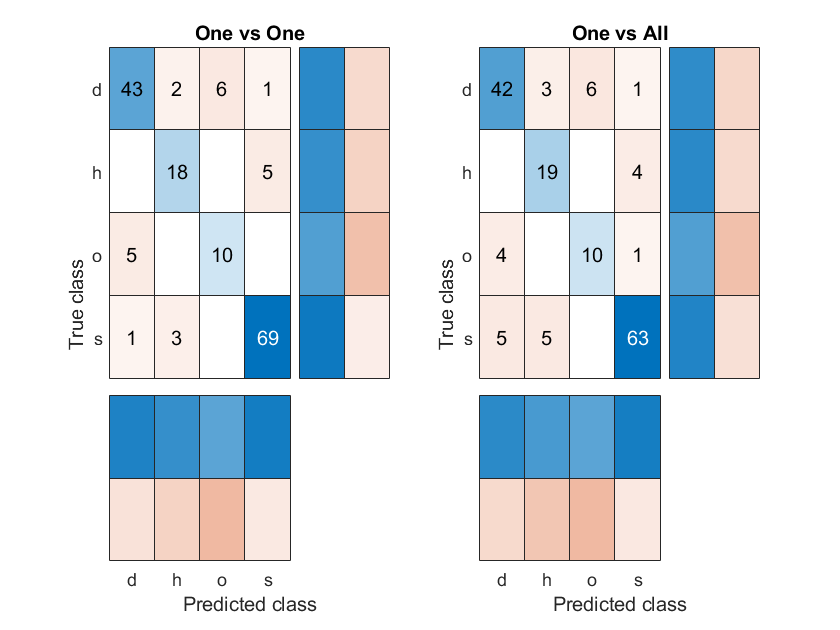

confusionchart(y_val_sp, pred_onevall, 'ColumnSummary','column-normalized','RowSummary','row-normalized');
title('One vs All')

The one vs one model perfoms better compared to all binary classifiers.

**Applying the models to the test data**

figure
subplot(1,2,1)
cat_y_test_sp = categorical(y_test_sp);
pred_onevone = svm_onevone.predict(x_test_sp);
disp("Accuracy (One v One): " + string(sum(pred_onevone == cat_y_test_sp) / length(cat_y_test_sp)))

Accuracy (One v One): 0.83951


confusionchart(y_test_sp, pred_onevone, 'ColumnSummary','column-normalized','RowSummary','row-normalized');
title('One vs One')
subplot(1,2,2)
pred_onevall = svm_onevall.predict(x_test_sp);
disp("Accuracy (One v All): " + string(sum(pred_onevall == cat_y_test_sp) / length(cat_y_test_sp)))

Accuracy (One v All): 0.83951


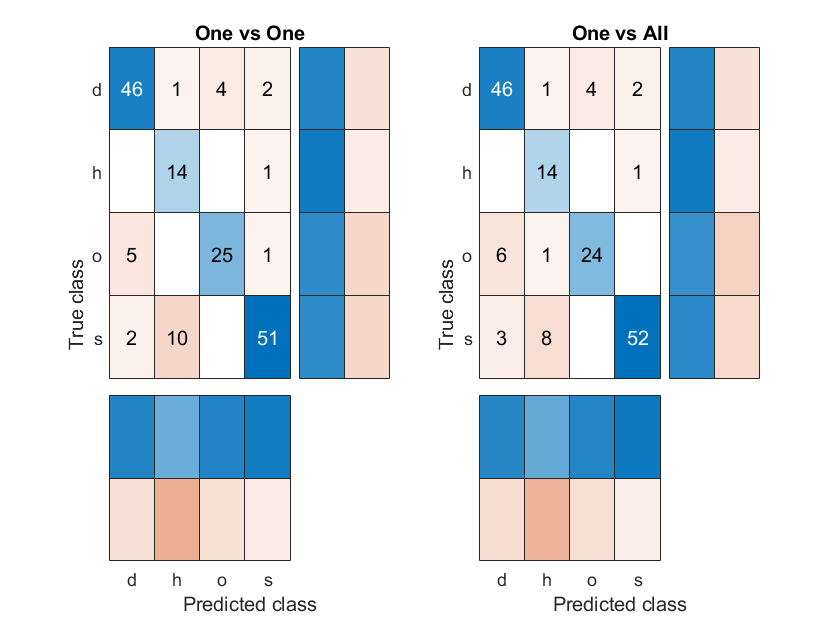

confusionchart(y_test_sp, pred_onevall, 'ColumnSummary','column-normalized','RowSummary','row-normalized');
title('One vs All')

figure
subplot(1,2,1)
cat_y_test_sp = categorical(y_test_sp);
pred_onevone = svm_onevone.predict(x_test_sp);
disp("Accuracy (One v One): " + string(sum(pred_onevone == cat_y_test_sp) / length(cat_y_test_sp)))

Accuracy (One v One): 0.83951


confusionchart(y_test_sp, pred_onevone, 'ColumnSummary','column-normalized','RowSummary','row-normalized');
title('One vs One')
subplot(1,2,2)
pred_CKNN = cknn_sp.predict(x_test_sp);
disp("Accuracy (One v All): " + string(sum(pred_CKNN == cat_y_test_sp) / length(cat_y_test_sp)))

Accuracy (One v All): 0.78395


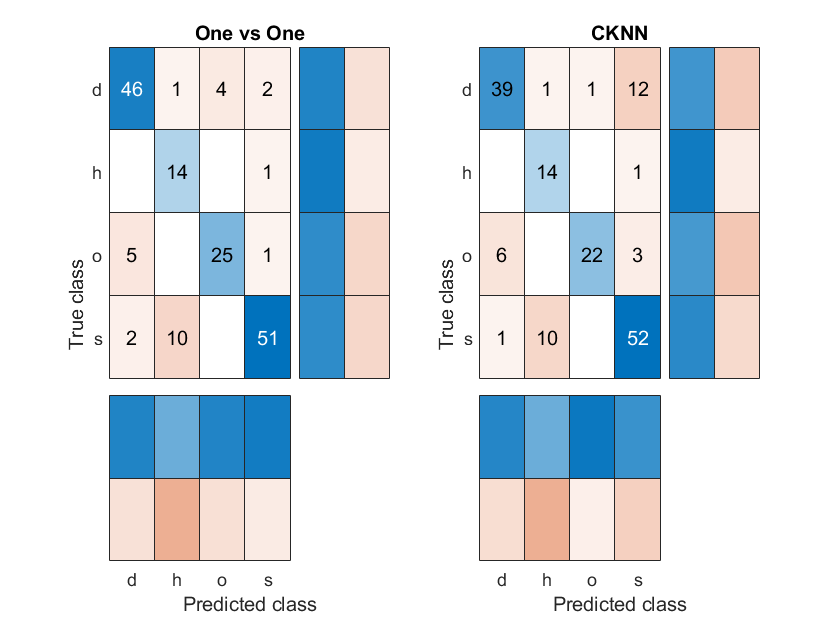

confusionchart(y_test_sp, pred_CKNN, 'ColumnSummary','column-normalized','RowSummary','row-normalized');
title('CKNN')